# Lab 2

Dr. Amr Amin

Ahmed Alqassas

Autumn 2024-25

## Review

**Sampling affects spatial resolution** by determining the density of pixels and, consequently, the level of detail captured in the image.

**Quantization affects intensity resolution** by determining how many different intensity values can be represented, impacting the image's tonal richness.

**Aliasing**: Occurs when the sampling rate is too low to capture the detail in the image, leading to distortion.

**Quantization Error**: The difference between the actual continuous intensity and the quantized value.

## Histograms

An image histogram is a *graphical* representation that shows the distribution of pixel intensity values in an image.

Applications: [Contrast enhancement, Thresholding, Analysis]

### Example 1: Create and Interpret Histogram

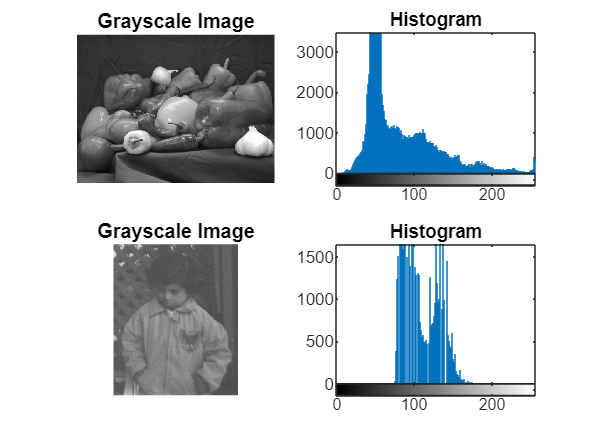

% read the image
img = imread('peppers.png');
img_2 = imread('pout.tif');

% for simplicity, convert rgb images into grayscale
gray_img = rgb2gray(img);

figure;
subplot(2,2,1)
imshow(gray_img);
title('Grayscale Image');
% show its histogram
subplot(2,2,2)
imhist(gray_img);
title('Histogram');
subplot(2,2,3)
imshow(img_2);
title('Grayscale Image');
% show its histogram
subplot(2,2,4)
imhist(img_2);
title('Histogram');

### Interpret the histogram

**Dark Image**: Histogram peaks at lower intensity values.

**Bright Image**: Histogram peaks at higher intensity values.

**Low Contrast**: Histogram is narrow and concentrated.

**High Contrast**: Histogram spans a wide range of intensity values.

### Example 2: Adjusting Contrast

**Contrast** refers to the difference in luminance or color that makes an object distinguishable.

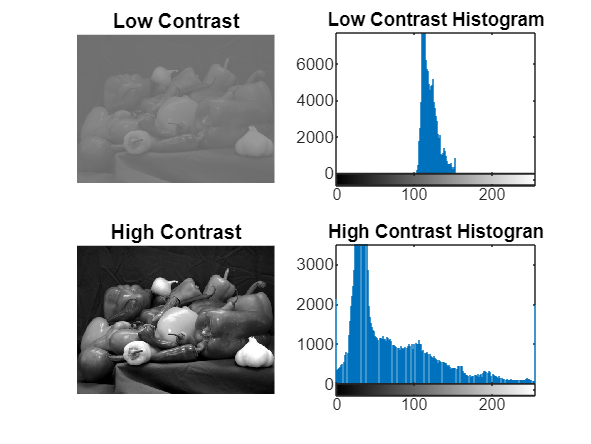

% Create low contrast image from the grayscale version
low_contrast = imadjust(gray_img, [0 1], [0.4 0.6]);

% Create high contrast image from the grayscale version
high_contrast = imadjust(gray_img, stretchlim(gray_img), [0 1]);

% Plotting
figure;
subplot(2,2,1);
imshow(low_contrast);
title('Low Contrast');

subplot(2,2,3);
imshow(high_contrast);
title('High Contrast');

subplot(2,2,2);
imhist(low_contrast);
title('Low Contrast Histogram')

subplot(2,2,4);
imhist(high_contrast);
title('High Contrast Histogran');

## Example 3: Histogram Equalization (Mathematically)

Histogram equalization is a** contrast enhancement** technique used in digital image processing. It improves the *global* contrast of an image by redistributing the intensity values so that they span the entire range of possible values.

In this example, we'll perform histogram equalization on a simple grayscale image with 8 intensity levels (0 to 7). We'll walk through each step mathematically to demonstrate how the process works.

### Solution

**Step 1:** Compute the Probability Density Function (PDF) using the formula: $p_k =\frac{n_k }{N}$

**Step 2: **The CDF accumulates the probabilities up to each intensity level using the formula: $s_{k\;} =\sum_{j=0}^k p_j$

**Step 3: **Compute the transformation function using the formula: $s_k^{\prime } =\left\lfloor \left(L-1\right)\times s_k \right\rfloor$, where $L$ is the number of intensity levels)

**Step 4**: Perform mapping to get the new frequencies.

***> The commands below are to help you check your calculations manually, next we'll perform histogram equalization with ***`histeq()`*** function in MATLAB***

% Create 8 intensity levels
r_k = 0:7

r_k =      0     1     2     3     4     5     6     7


% Initialize the original frequencies
n_k = [0, 0, 10, 10, 20, 20, 4, 0]

n_k =      0     0    10    10    20    20     4     0


N = sum(n_k)

N = 64

% Calculate the PDF
p_k = n_k / N

p_k =          0         0    0.1562    0.1562    0.3125    0.3125    0.0625         0


% Calculate the CDF
s_k = cumsum(p_k)

s_k =          0         0    0.1562    0.3125    0.6250    0.9375    1.0000    1.0000


L = 8

L = 8

% Apply transfotmation
s_k_new = floor((L-1) * s_k)

s_k_new =      0     0     1     2     4     6     7     7


% If your calculations are right, these are the new frequencies after
% mapping.
n_k_new = [0, 10, 10, 0, 20, 0, 20, 4]

n_k_new =      0    10    10     0    20     0    20     4


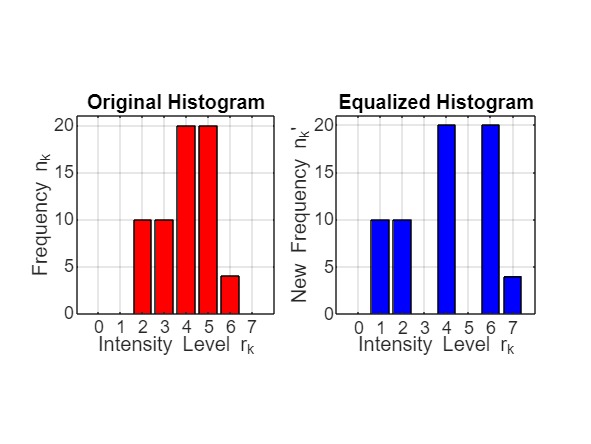

figure;
% Plot the original histogram
subplot(1,2,1)
bar(r_k, n_k, 'FaceColor', [1.0 0.0 0.0]);
title('Original Histogram');
xlabel('Intensity Level r_k');
ylabel('Frequency n_k');
xlim([-1.0 L]);
xticks(0:L-1);
ylim([0 max(n_k)+1]);
grid on
axis square
% Plot the equalized histogram
subplot(1,2,2)
bar(r_k, n_k_new, 'FaceColor', [0.0 0.0 1.0]);
title('Equalized Histogram');
xlabel('Intensity Level r_k');
ylabel("New Frequency n_k'");
xlim([-1.0 L]);
xticks(0:L-1);
ylim([0 max(n_k)+1]);
grid on
axis square

## Example 4: Histogram Equalization with `histeq()`

In this example we will use a new image other than the `peppers.png`. This is because it has a good contrast and applying histogram equalization on it will result in **unwanted** **over enhancement**. If you replaced the `pout.tif` image in the code below with the `peppers.png` you will get the following results:

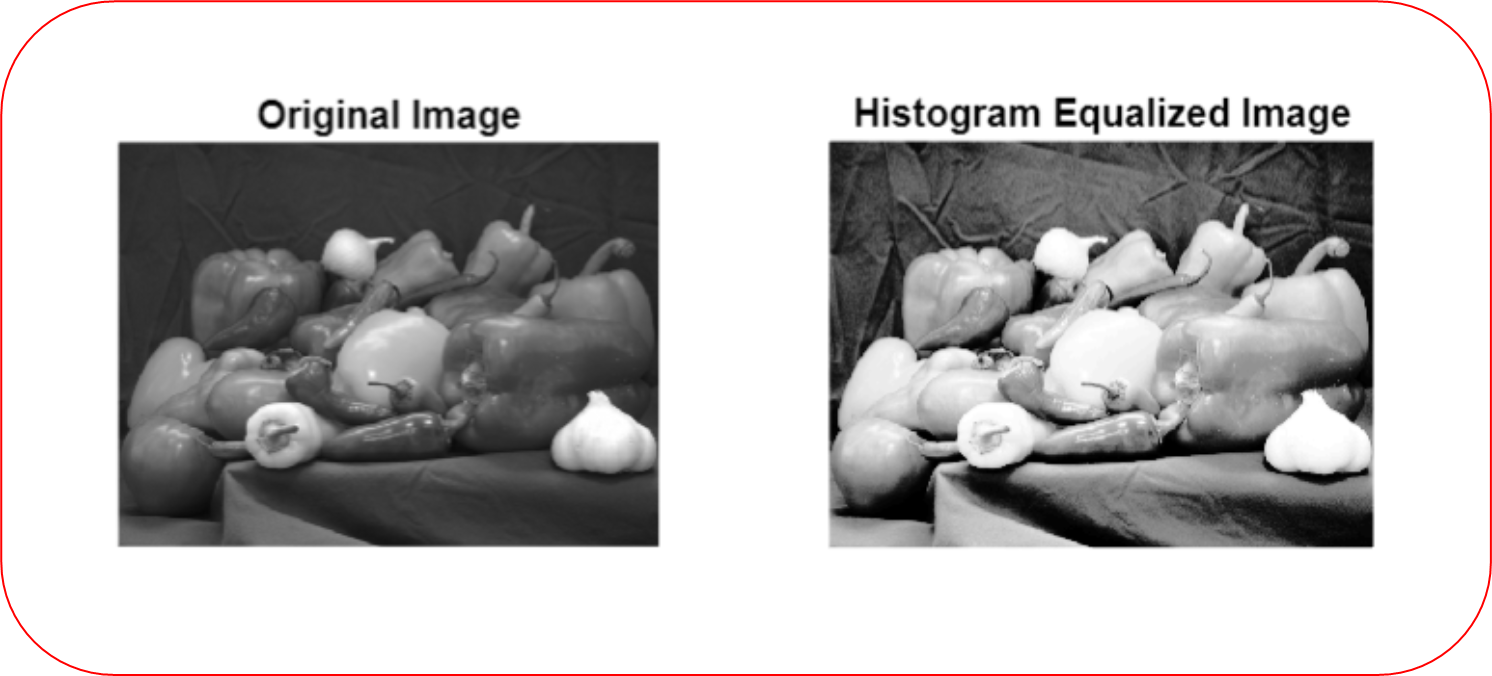

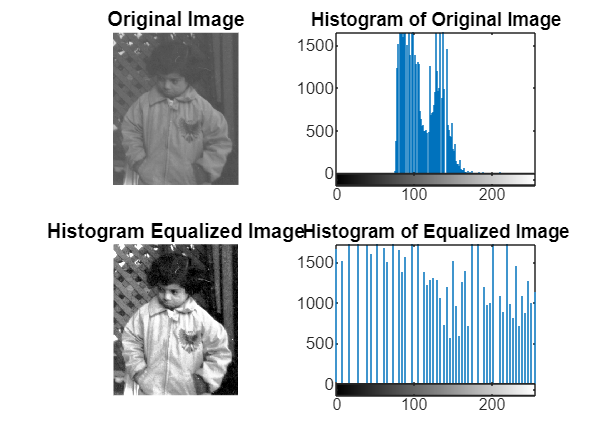

% Import the image with bad contrast
org_img = imread('pout.tif');

% Apply histogram equalization
equalized_image = histeq(org_img);

% Display the original image
figure;
subplot(2, 2, 1);
imshow(org_img);
title('Original Image');

% Display the equalized image
subplot(2,2,3);
imshow(equalized_image)
title('Histogram Equalized Image');

% Display the histogram of the original image
subplot(2,2,2);
imhist(org_img);
title('Histogram of Original Image');

% Display the histogram of the equalized image
subplot(2,2,4);
imhist(equalized_image);
title('Histogram of Equalized Image');

***Becareful when using Histogram Equaliztion as it has the following limitations:***

- **Over-enhancement:** May amplify noise in homogeneous regions.

- **Global Adjustment:** Affects the entire image uniformly, which might not be ideal for images with localized contrast issues.

- **Loss of Original Intensity Relationships:** The process can alter the original intensity relationships, which might be important in some applications.